Ejemplo de diseño y aplicación de filtros digitales

Inicialmente se cre una señal de prueba con varios armónicos para observar el desempñeo de los filtros

También se calcula su espectro de frecuencia usando la FFT

n=0:511;% vector de tiempo
k=n/512;% vector de frecuencias
xn=sin(2*pi*n*1/4)+sin(2*pi*n*1/8)+sin(2*pi*n*1/32)+sin(2*pi*n*1/128);
xk=abs(fft(xn));

Se grafican la señal y su respectivo espectro de frecuencia

Identifique cada frecuancia y su ubicación en el dominio de la frecuencia

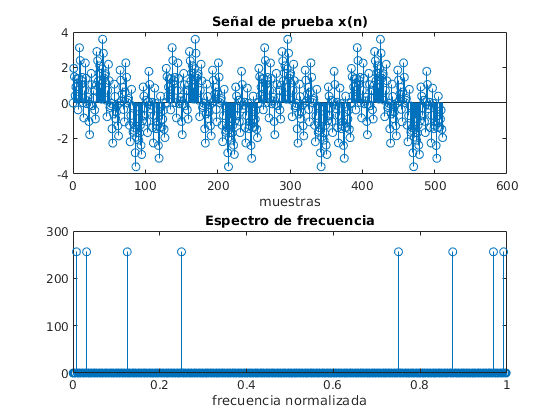

figure()
subplot(2,1,1);
stem(n,xn);
xlabel('muestras')
title('Señal de prueba x(n)');
subplot(2,1,2);
stem(k,xk);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Se crea un filtro pasa-bajos digital utilizando el método de enventanado. Mediante la función fir1 se obtienen los coeficientes de la función de transferencia del filtro.

La frecuencia de corte corresponde a


$$\frac{1}{32}\;\left(\frac{ciclos}{muestra}\right)=\frac{1}{16}\;\left(\frac{\pi rad}{muestra}\right)$$


Observe las unidades de frecuencia que utiliza matlab

h1n=fir1(50,1/16); 

A continuación se grafica la respuesta en frecuencia del filtro mediante el comando freqz. Como se trata de un filtro fir, note el uso del valor 1 para el denominador de la función de transferencia

Haciendo zoom sobre la figura, trate de ubicar el punto más cercano a la frecuencia de corte (ganancia -3 dB)

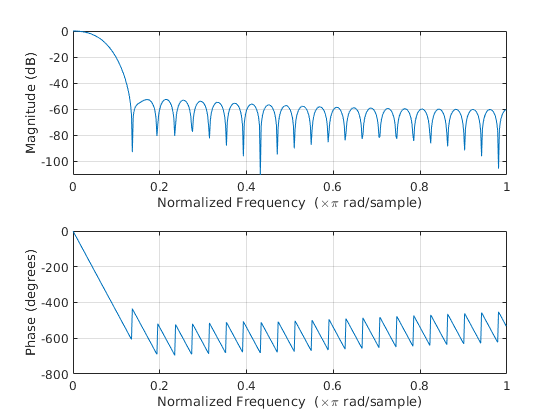

figure();
freqz(h1n,1);

La grafica superior corresponde a la ganancia del filtro, mientras la inferior corresponde la fase. Note la forma de la respuesta en fase. 

La aplicación del filtro sobre la señal se hace mediante la función filter

y1n=filter(h1n,1,xn);
y1k=abs(fft(y1n));

Se procede a graficar la señal resultante y su espcetro de frecuencia. Compare con las originales y advierta los cambios

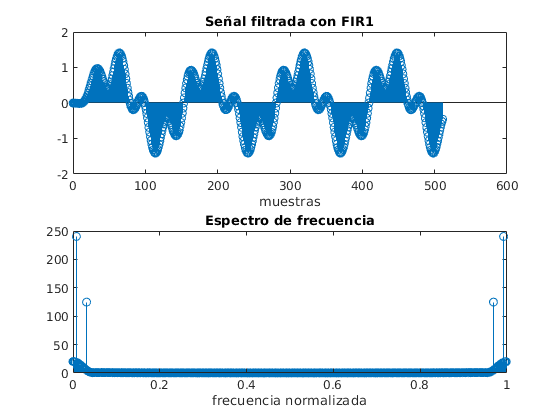

figure()
subplot(2,1,1)
stem(n,y1n);
xlabel('muestras')
title('Señal filtrada con FIR1');
subplot(2,1,2);
stem(k,y1k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Para la siguiente parte del ejemplo se aplicará el método de diseño de filtros FIR denominado muestreo en frecuencia.

Este método de diseño se aplica mediante la función fir2

R=63; %numero de muestras sobre el dominio de la frecuancia
E=4; %ubicación de la frec de corte sobre el arreglo
F=[0:R]/R; % Normalización de los valores de frecuencia
A=[ones(1,E),zeros(1,R-E+1)]; %valores de ganancia
h2n=fir2(50,F,A);

Se aplica el filtro usando filter y se obtiene la representación en frecuencia de la señal filtrada usando la FFT.

Freqz permite ver la respuesta en frecuancia del filtro (ganancia y fase)

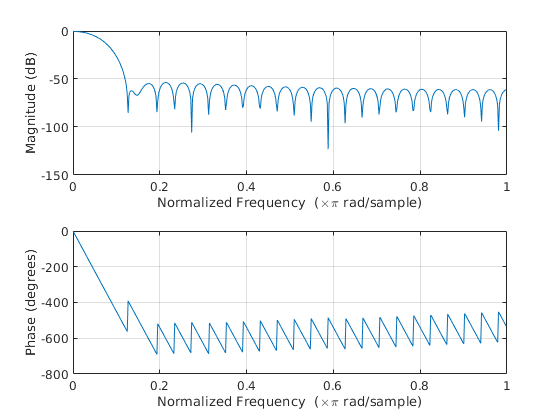

y2n=filter(h2n,1,xn);
y2k=abs(fft(y2n));
figure();
freqz(h2n,1);

Se grafican los resultados. Compare con las señales originales e identifique los cambios.

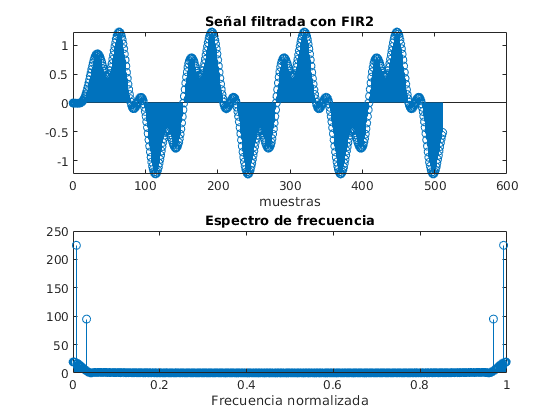

figure()
subplot(2,1,1);
stem(n,y2n);
xlabel('muestras')
title('Señal filtrada con FIR2');
subplot(2,1,2);
stem(k,y2k);
xlabel('Frecuencia normalizada')
title('Espectro de frecuencia');

El siguiente y último método es el método conocido como Park's MacClellan que se aplica usando la función firpm

R=63;% muestras en el dominio de la frecuencia
E=4;%ubicacion de la frec de corte en el arreglo
F=[0:R]/R; % valores de frecuencia normalizada
A=[ones(1,E),zeros(1,R-E+1)];% Ganancias del filtro
h3n=firpm(50,F,A);

Se aplica el filtro mediante la función filter y se obtiene la representación en frecuencia de la señal filtrada. Mediante freqz se obtiene la respuesta en frecuancia del filtro (ganancia y fase)

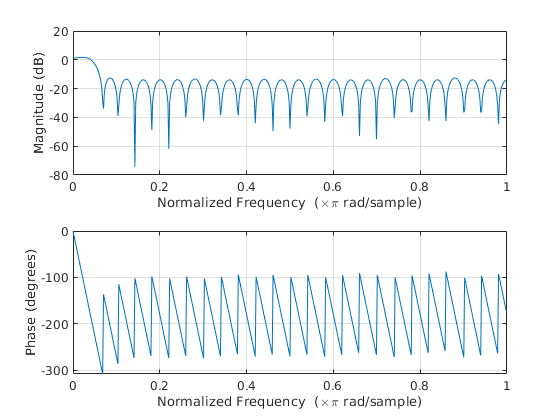

y3n=filter(h3n,1,xn);
y3k=abs(fft(y3n));
figure();
freqz(h3n,1);

Por último se grafican la señal filtrada y su espectro

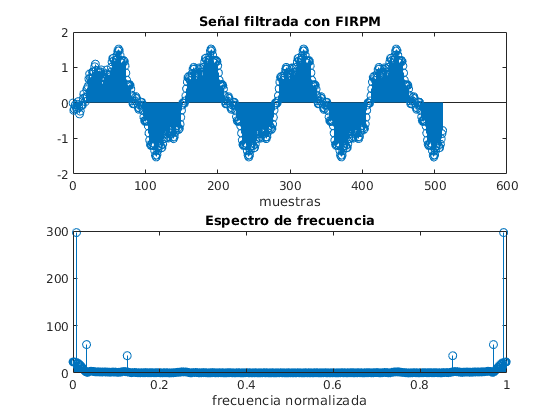

figure()
subplot(2,1,1)
stem(n,y3n);
xlabel('muestras')
title('Señal filtrada con FIRPM');
subplot(2,1,2);
stem(k,y3k);
xlabel('frecuencia normalizada')
title('Espectro de frecuencia');

Compare el desempeño de los filtros. Analice en el dominio de la frecuencia cerca de la frecuencia de corte.

¿Cómo se puede determinar cuál de los tres filtros es mejor?